data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;

% 2.1 
eye(2);
G1 = FWT(1:2,1:2);
s = tf('s');
G = G1.C*inv((s*eye(5)-G1.A))*G1.B;
omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
    end
RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



% 2.5 
G=tf(FWT(1:2,1:2));

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])

Wp11 =
 
  0.3333 s + 1.885
  ----------------
   s + 0.0001885
 
Continuous-time transfer function.



Wp=[Wp11 0; 0 wB2] %

Wp =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.




% Control weights
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




Plant=augw(G,Wp,Wu,[]) % build plant

Plant =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1   -0.0001885           0           0      0.1598    0.001658      0.4338   -0.006493      0.1383
   x2            0     -0.0014   -0.001024           0           0           0           0           0
   x3            0   0.0009766           0           0           0           0           0           0
   x4            0           0           0     -0.5979      -2.744      -1.177      -0.271     -0.3654
   x5            0           0           0           4           0           0           0           0
   x6            0           0           0           0           1           0           0           0
   x7            0           0           0           0           0         0.5           0           0
   x8            0           0           0           0           0           0        0.25           0
   x9            0           0           0           0  

P=minreal(Plant) % to check number of states

5 states removed.

P =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.2131    -0.0295    0.03336       -1.3     0.4763     0.1823    0.02628    0.05079
   x2     0.4143   -0.02882   -0.00703     0.2492    -0.4512  -0.008475   -0.03462   -0.02736
   x3     0.1295     0.2552    0.03197    -0.1315     0.2071    0.06565    0.06406    0.02923
   x4     0.7125    -0.1849     0.2443     0.1779      -3.35     -1.207    -0.3706    -0.3839
   x5     -1.216    -0.1159    -0.3458      2.574    -0.6483    -0.5263   -0.05786     -0.166
   x6    -0.3994   -0.05239   -0.07982     0.6352    -0.2924    -0.2267   -0.03432   -0.06571
   x7    0.09169   -0.03565   0.009626     0.2942    -0.1525   0.008626   -0.01609  -0.002359
   x8    -0.5212    0.02677    -0.1553     0.2231    -0.2404    -0.3302   -0.02251    -0.1025
 
  B = 
                ?           ?  Beta (deg)  tau_e (Nm)
   x1    -0.05644           0    -0.05566     0.01069
   x2

% 2.7

[K2,CL2,GAM2,INFO2] = hinfsyn(P,2,2)

K2 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1    3.961   -3.657    26.43  -0.8697   -4.947    56.91    38.81     -102
   x2   -4.507    5.153   -28.35  -0.5758    4.313   -59.41   -41.93    111.8
   x3    1.721   -1.402     11.2  0.07794   -2.021    23.92    16.52   -43.44
   x4    9.397   -8.705    60.68     1.22   -15.61    128.4    88.47   -234.3
   x5   -38.34    37.03   -246.7    -2.36     47.3     -526   -362.6    957.6
   x6   -16.73    16.42   -103.1   -1.706    18.94     -219   -151.9    402.1
   x7     11.9   -13.67    49.85     3.02   -4.805    99.17    74.56   -204.5
   x8   0.3747   -1.015   -5.538   0.6756    2.518   -14.03   -7.744    18.14
 
  B = 
               u1          u2
   x1    -0.05644  -2.414e-17
   x2    -0.01836   2.793e-16
   x3      0.1752   2.343e-17
   x4   -0.005187  -1.743e-17
   x5    -0.03134  -2.701e-17
   x6       0.279   2.794e-17
   x7      0.3098  -1.356e-16
   x8     -0.8893   5.203e-17
 
  C

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [2×8 double]
       Kw: [2×8 double]
       Lx: [8×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]



%Nyquist plot
LoopT=G*K2+eye(2);
PolesL=pole(minreal(LoopT));

10 states removed.


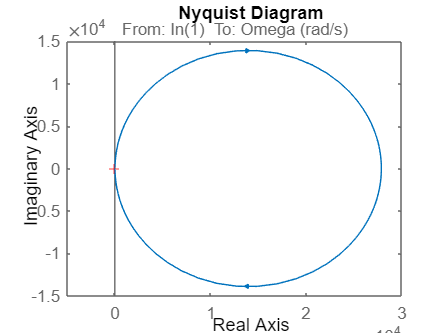

nyqDet=LoopT(1,1)*LoopT(2,2)-LoopT(1,2)*LoopT(2,1);
nyquist(nyqDet)

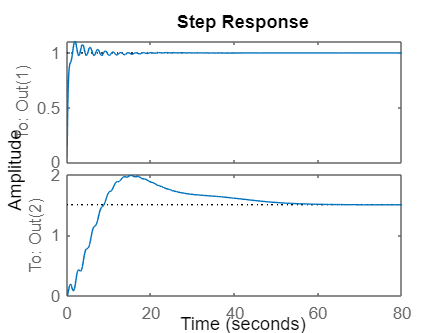

% 2.8 

% Calculate S and T
Sens=(1/Wp)*CL2(1:2,1:2);
Compl=eye(2)-Sens;

% Step in reference
step(Compl(1:2,1))

stepinfo(Compl(1:2,1))

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


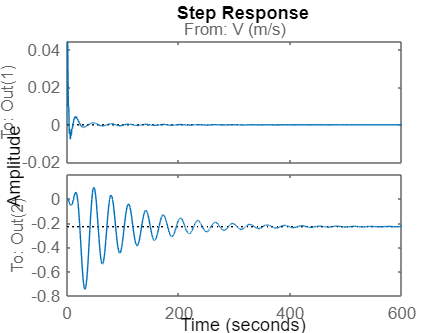



% Plot influence of step in disturbance
D_rej=Sens*FWT(1:2,3);
step(D_rej)

stepinfo(D_rej)

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime
